# Guía 1 - Ejercicio 3

## Enunciado:

 Simular un modelo de Ising en una y dos dimensiones. Encontrar latemperatura crítica para ambos casos. 

## Ising 1D

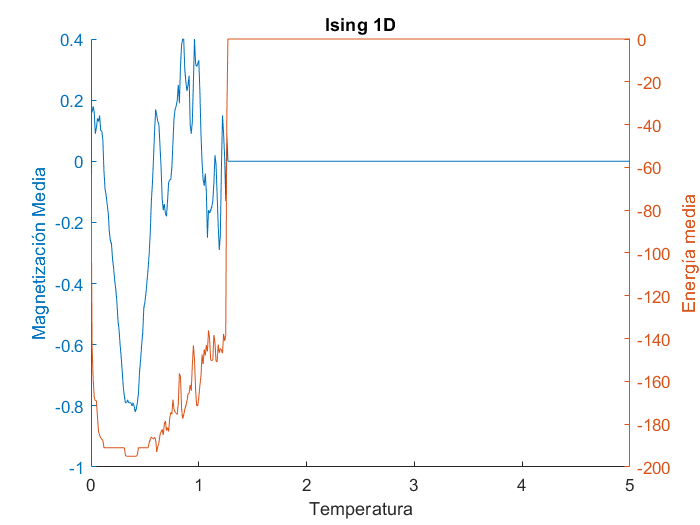

N=200;
S_1d = rand([N 1])<0.5;
S_1d = 2*S_1d-1;
S_1d = negSign(S_1d);
w = zeros([N N]);
for i=2:(N-1)
    w(i,i+1)=1;
    w(i,i-1)=1;
end
w(1,2)=1;
w(N,N-1)=1;
%imshow(w,'InitialMagnification','fit')
orden = randperm(N);

S_medio = zeros([501 1]);
H_medio = zeros([501 1]);
for T=0:0.01:5
    H = zeros([N 1]);
    for i=1:N
        H_inicial=-1/2*S_1d'*w*S_1d;
        S_1d(orden(i))=S_1d(orden(i))*-1;
        H_final=-1/2*S_1d'*w*S_1d;
        if H_final<H_inicial
            H(i) = H_final;
            continue
        else 
            if rand(1)<exp(-1*(H_final-H_inicial)/T)
                H(i)=H_final;
                continue
            else 
                S_1d(orden(i))=S_1d(orden(i))*-1;
                H(i)=H_inicial;
            end
        end        
    end
    S_medio(int8(T*100)+1)=mean(S_1d);
    H_medio(int8(T*100)+1)=mean(H);

end
close all
figure()
hold on
yyaxis left
plot(0:0.01:5,S_medio)
ylabel('Magnetización Media')
yyaxis right
plot(0:0.01:5,H_medio)
ylabel('Energía media')
xlabel('Temperatura')
title('Ising 1D')

## Ising 2D

N=30;
S_2d = rand([N N])<0.5;
S_2d = 2*S_2d-1;
S_2d = negSign(S_2d);
S_2d_vector = S_2d(:);
w = zeros([N^2 N^2]);
for i=1:N^2
    if i==1
        w(i,i+1)=1;
        w(i,i+N)=1;
    elseif i==N
        w(i,i-1)=1;
        w(i,i+N)=1;
    elseif i==(N^2-N+1)
        w(i,i+1)=1;
        w(i,i-N)=1;
    elseif i==N^2
        w(i,i-1)=1;
        w(i,i-N)=1;
    elseif i<N 
        w(i,i+1)=1;
        w(i,i-1)=1;
        w(i,i+N)=1;
    elseif mod(i-1,N)==0
        w(i,i+1)=1;
        w(i,i-N)=1;
        w(i,i+N)=1;
    elseif mod(i,N)==0
        w(i,i-1)=1;
        w(i,i-N)=1;
        w(i,i+N)=1;
    elseif i>N^2-N
        w(i,i+1)=1;
        w(i,i-1)=1;
        w(i,i-N)=1;
    else
        w(i,i+1)=1;
        w(i,i-1)=1;
        w(i,i-N)=1;
        w(i,i+N)=1;
    end
end
%imshow(w,'InitialMagnification','fit')
orden = randperm(N^2);

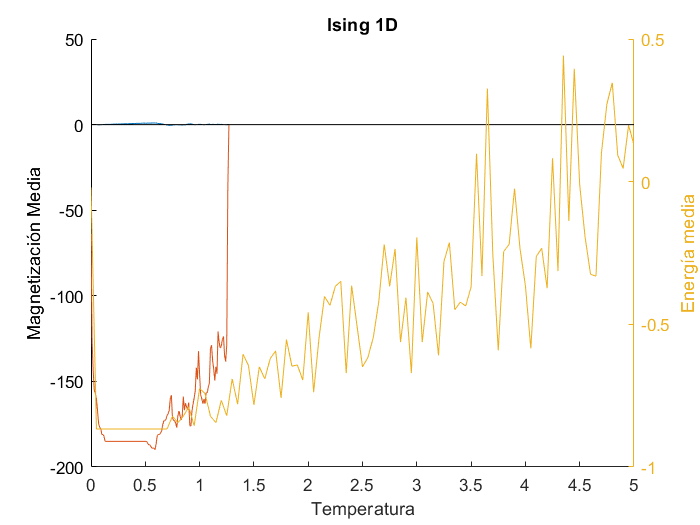



H_medio = zeros([101 1]);
S_medio = zeros([101 1]);
for T=0:0.05:5
    H = zeros([N^2 1]);
    for i=1:N
        H_inicial=-1/2*S_2d_vector'*w*S_2d_vector;
        S_2d_vector(orden(i))=S_2d_vector(orden(i))*-1;
        H_final=-1/2*S_2d_vector'*w*S_2d_vector;
        if H_final<H_inicial
            H(i) = H_final;
            continue
        else 
            if rand(1)<exp(-1*(H_final-H_inicial)/T)
                H(i)=H_final;
            else 
                S_2d_vector(orden(i))=S_2d_vector(orden(i))*-1;
                H(i)=H_inicial;
            end
        end        
    end
    H_medio(int8(T*20)+1)=mean(H);
    S_medio(int8(T*20)+1)=mean(S_2d_vector);

end
close all
figure(2)
hold on
yyaxis left
plot(0:0.05:5,S_medio)
ylabel('Magnetización Media')
yyaxis right
plot(0:0.05:5,H_medio)
ylabel('Energía media')
xlabel('Temperatura')
title('Ising 1D')